clear all
close all

addpath("Immagini\04_rumoreTemp")

Tm30 = double(imread("Tm30_X1.tif"));
Tm25 = double(imread("Tm25_X1.tif"));
Tm20 = double(imread("Tm20_X1.tif"));
Tm15 = double(imread("Tm15_X1.tif"));
Tm10 = double(imread("Tm10_X1.tif"));
Tm05 = double(imread("Tm05_X1.tif"));
Tp00 = double(imread("Tp00_X1.tif"));
Tp05 = double(imread("Tp05_X1.tif"));
Tp10 = double(imread("Tp10_X1.tif"));
Tp15 = double(imread("Tp15_X1.tif"));

error_mean = [];
error_sigma = [];

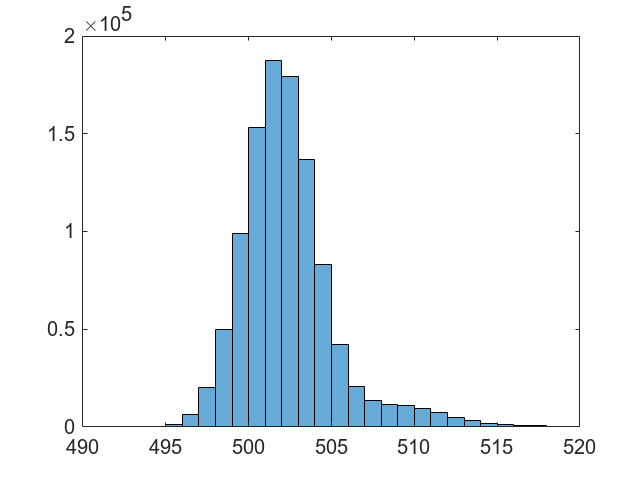

dist = histogram(Tm30, -2^15:1:2^15);
xlim([490 520])

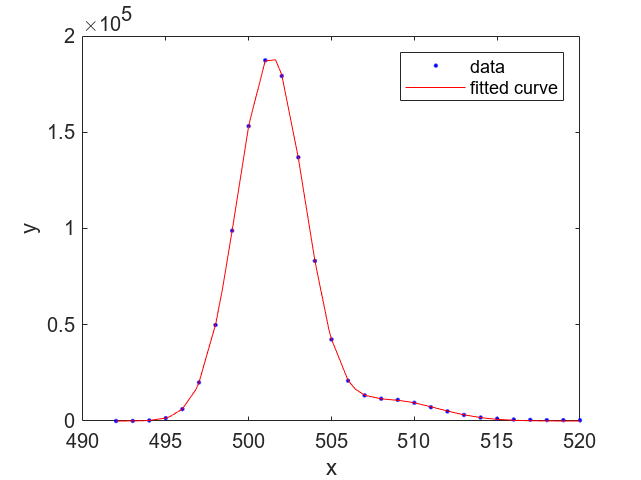


counts = dist.Values;
mask = counts~=0;
y = counts(mask);

bins = dist.BinEdges;
x = round(bins(mask));

gaus = fit(x.',y.','gauss2');
plot(gaus,x,y)
xlim([490 520])


mean_m30 = gaus.b1

mean_m30 = 501.3236

sigma_m30 = gaus.c1/sqrt(2)

sigma_m30 = 2.0387


[e_mean, e_sigma] = fit_error(gaus)

e_mean = 0.0020

e_sigma = 0.0018

error_mean = [error_mean; e_mean];
error_sigma = [error_sigma; e_sigma];

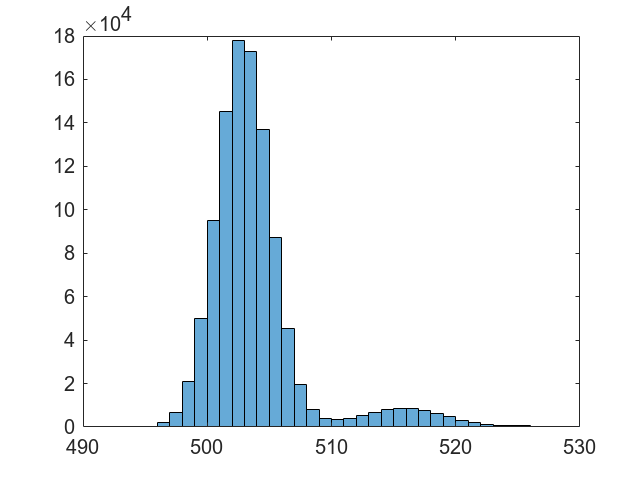

dist = histogram(Tm25, -2^15:1:2^15);
xlim([490 530])

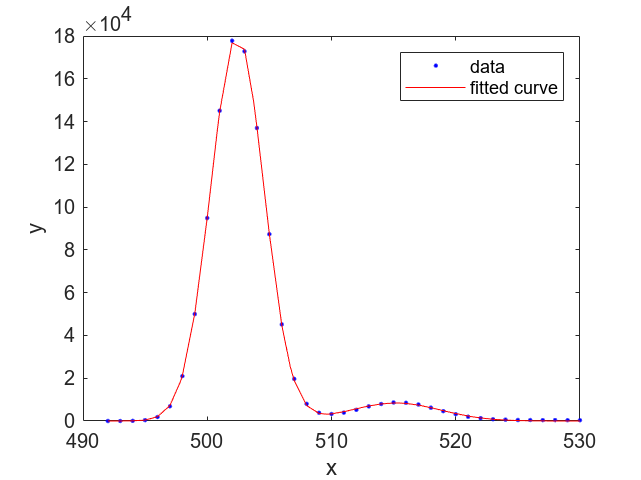


counts = dist.Values;
mask = counts~=0;
y = counts(mask);

bins = dist.BinEdges;
x = round(bins(mask));

gaus = fit(x.',y.','gauss2');
plot(gaus,x,y)
xlim([490 530])


mean_m25 = gaus.b1

mean_m25 = 502.4198

sigma_m25 = gaus.c1/sqrt(2)

sigma_m25 = 2.1409


[e_mean, e_sigma] = fit_error(gaus)

e_mean = 0.0022

e_sigma = 0.0022

error_mean = [error_mean; e_mean];
error_sigma = [error_sigma; e_sigma];

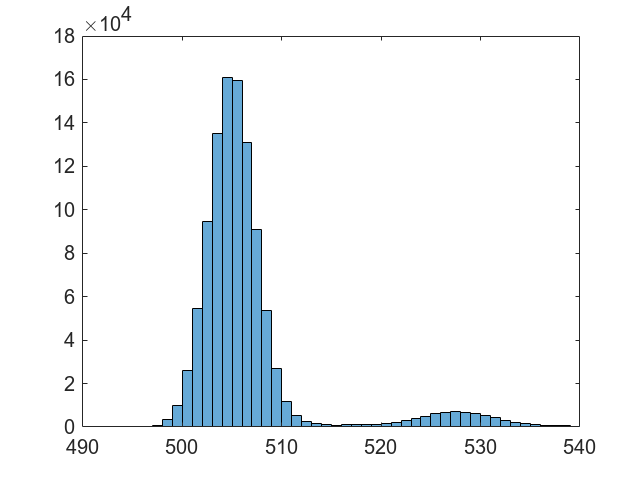

dist = histogram(Tm20, -2^15:1:2^15);
xlim([490 540])

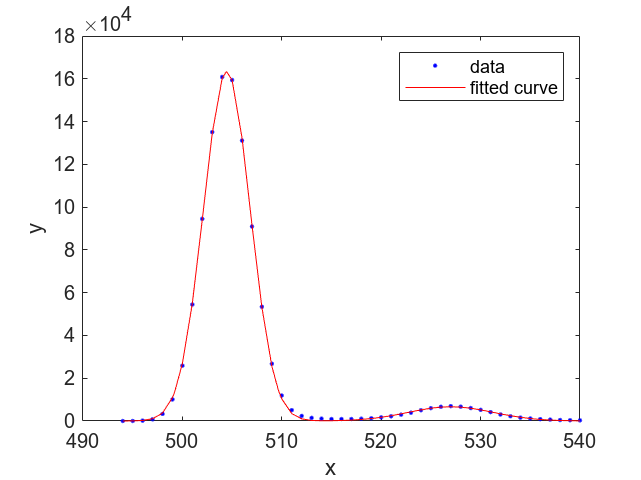


counts = dist.Values;
mask = counts~=0;
y = counts(mask);

bins = dist.BinEdges;
x = round(bins(mask));

gaus = fit(x.',y.','gauss2', 'Exclude', x>590);
plot(gaus,x,y)
xlim([490 540])


mean_m20 = gaus.b1

mean_m20 = 504.4701

sigma_m20 = gaus.c1/sqrt(2)

sigma_m20 = 2.3526


[e_mean, e_sigma] = fit_error(gaus)

e_mean = 0.0092

e_sigma = 0.0092

error_mean = [error_mean; e_mean];
error_sigma = [error_sigma; e_sigma];

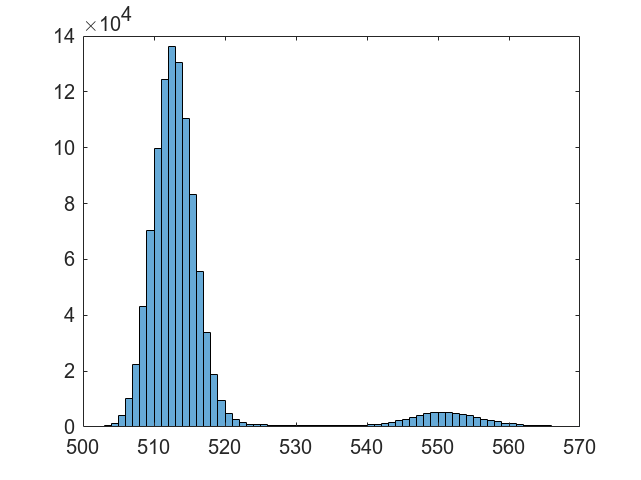

dist = histogram(Tm15, -2^15:1:2^15);
xlim([500 570])

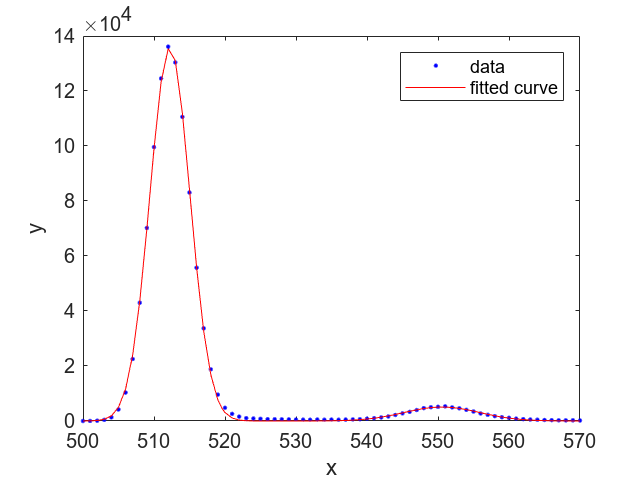


counts = dist.Values;
mask = counts~=0;
y = counts(mask);

bins = dist.BinEdges;
x = round(bins(mask));

gaus = fit(x.',y.','gauss2', 'Exclude', x>1500);
plot(gaus,x,y)
xlim([500 570])


mean_m15 = gaus.b1

mean_m15 = 512.2425

sigma_m15 = gaus.c1/sqrt(2)

sigma_m15 = 2.8172


[e_mean, e_sigma] = fit_error(gaus)

e_mean = 0.0064

e_sigma = 0.0064

error_mean = [error_mean; e_mean];
error_sigma = [error_sigma; e_sigma];

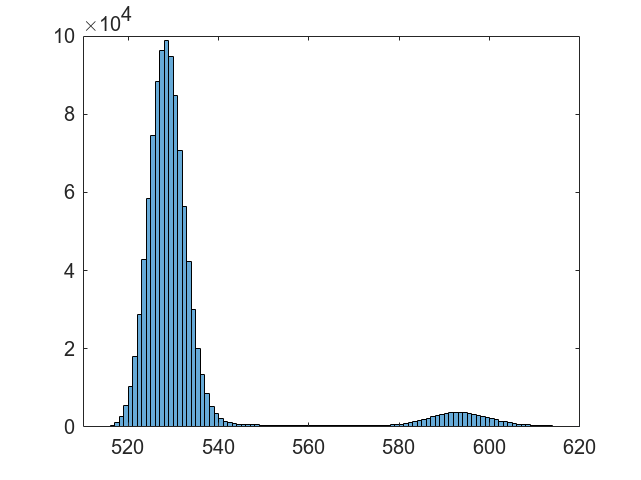

dist = histogram(Tm10, -2^15:1:2^15);
xlim([510 620])

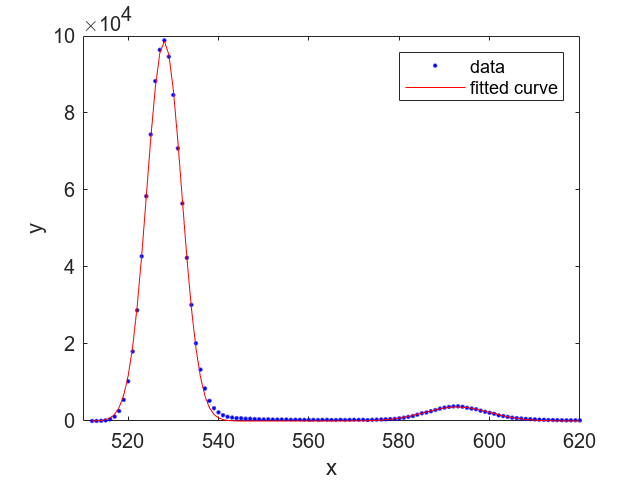


counts = dist.Values;
mask = counts~=0;
y = counts(mask);

bins = dist.BinEdges;
x = round(bins(mask));

gaus = fit(x.',y.','gauss2');
plot(gaus,x,y)
xlim([510 620])


mean_m10 = gaus.b1

mean_m10 = 527.9716

sigma_m10 = gaus.c1/sqrt(2)

sigma_m10 = 3.8655


[e_mean, e_sigma] = fit_error(gaus)

e_mean = 0.0095

e_sigma = 0.0095

error_mean = [error_mean; e_mean];
error_sigma = [error_sigma; e_sigma];

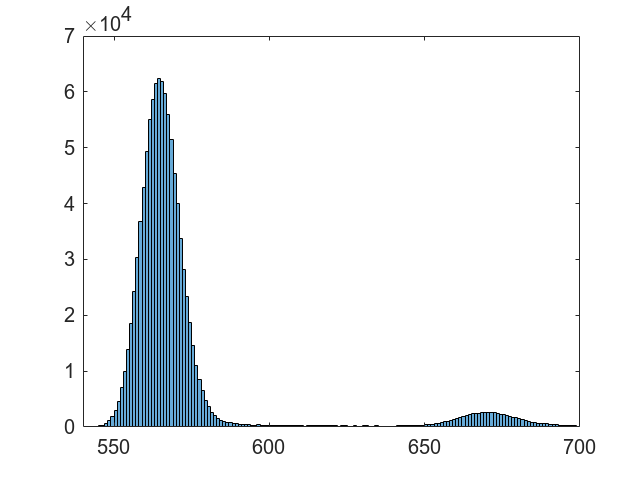

dist = histogram(Tm05, -2^15:1:2^15);
xlim([540 700])

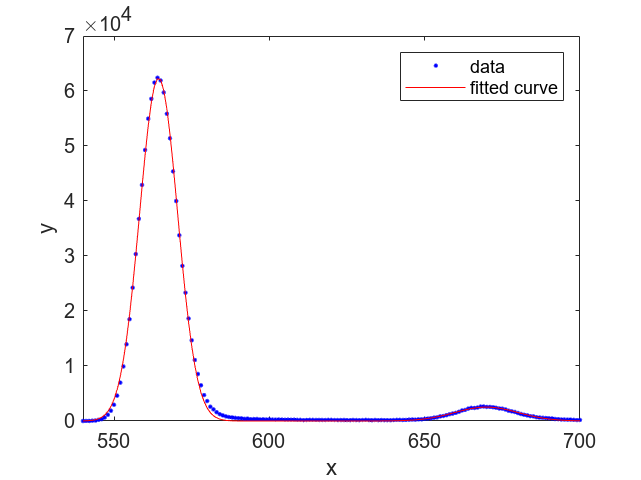


counts = dist.Values;
mask = counts~=0;
y = counts(mask);

bins = dist.BinEdges;
x = round(bins(mask));

gaus = fit(x.',y.','gauss2');
plot(gaus,x,y)
xlim([540 700])


mean_m05 = gaus.b1

mean_m05 = 564.3452

sigma_m05 = gaus.c1/sqrt(2)

sigma_m05 = 6.1073


[e_mean, e_sigma] = fit_error(gaus)

e_mean = 0.0147

e_sigma = 0.0147

error_mean = [error_mean; e_mean];
error_sigma = [error_sigma; e_sigma];

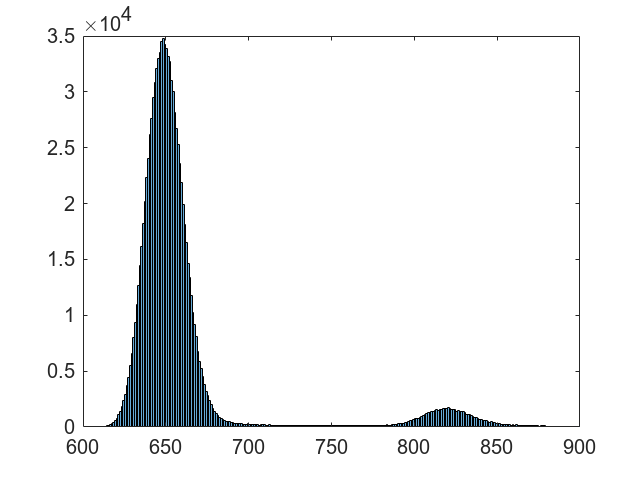

dist = histogram(Tp00, -2^15:1:2^15);
xlim([600 900])

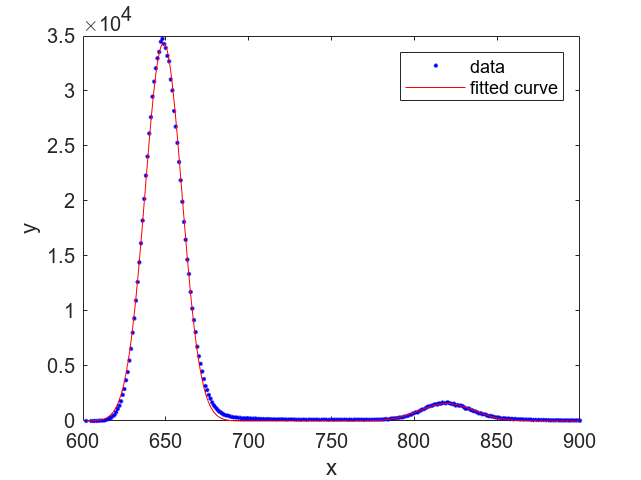


counts = dist.Values;
mask = counts~=0;
y = counts(mask);

bins = dist.BinEdges;
x = round(bins(mask));

gaus = fit(x.',y.','gauss2');
plot(gaus,x,y)
xlim([600 900])


mean_p00 = gaus.b1

mean_p00 = 648.5671

sigma_p00 = gaus.c1/sqrt(2)

sigma_p00 = 11.0997


[e_mean, e_sigma] = fit_error(gaus)

e_mean = 0.0247

e_sigma = 0.0247

error_mean = [error_mean; e_mean];
error_sigma = [error_sigma; e_sigma];

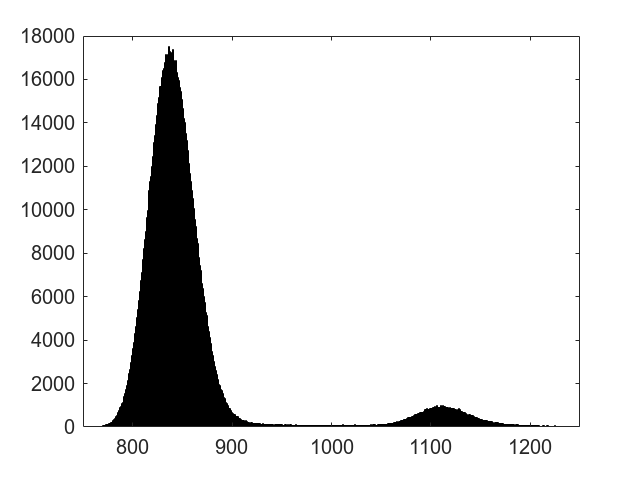

dist = histogram(Tp05, -2^15:1:2^15);
xlim([750 1250])

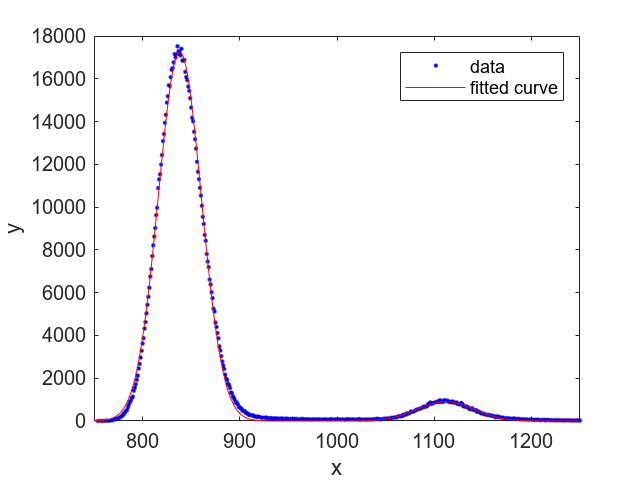


counts = dist.Values;
mask = counts~=0;
y = counts(mask);

bins = dist.BinEdges;
x = round(bins(mask));

gaus = fit(x.',y.','gauss2');
plot(gaus,x,y)
xlim([750 1250])


mean_p05 = gaus.b1

mean_p05 = 838.2319

sigma_p05 = gaus.c1/sqrt(2)

sigma_p05 = 22.1940


[e_mean, e_sigma] = fit_error(gaus)

e_mean = 0.0472

e_sigma = 0.0472

error_mean = [error_mean; e_mean];
error_sigma = [error_sigma; e_sigma];

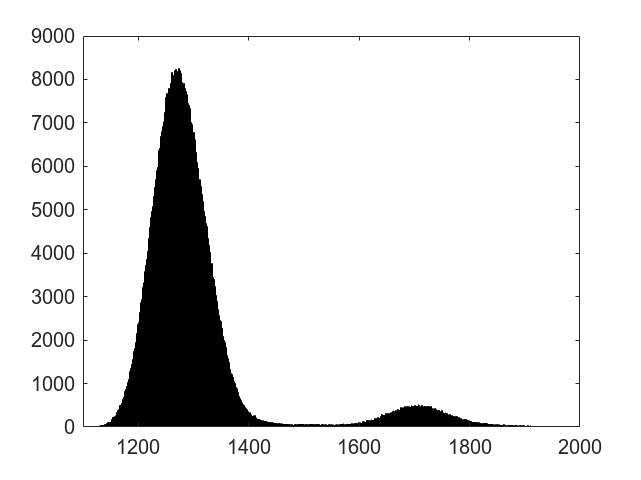

dist = histogram(Tp10, -2^15:1:2^15);
xlim([1100 2000])

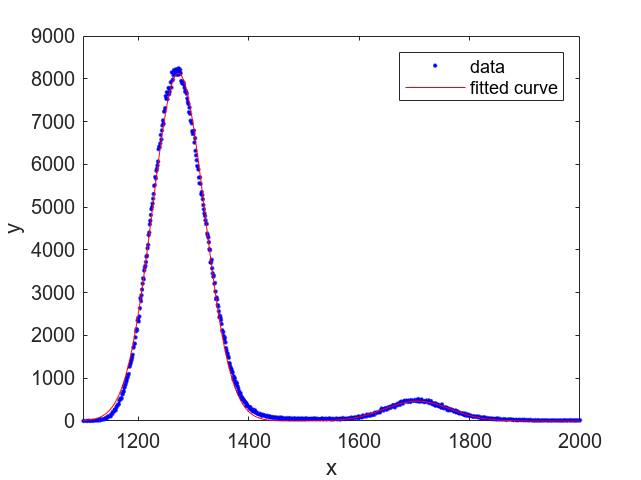


counts = dist.Values;
mask = counts~=0;
y = counts(mask);

bins = dist.BinEdges;
x = round(bins(mask));

gaus = fit(x.',y.','gauss2');
plot(gaus,x,y)
xlim([1100 2000])


mean_p10 = gaus.b1

mean_p10 = 1.2728e+03

sigma_p10 = gaus.c1/sqrt(2)

sigma_p10 = 47.3545


[e_mean, e_sigma] = fit_error(gaus)

e_mean = 0.0942

e_sigma = 0.0942

error_mean = [error_mean; e_mean];
error_sigma = [error_sigma; e_sigma];

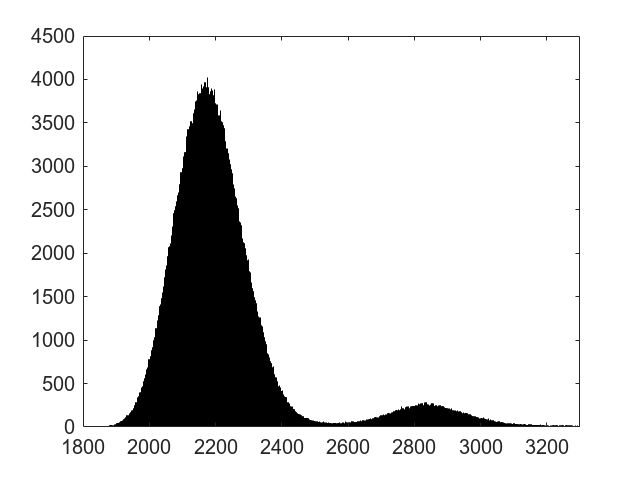

dist = histogram(Tp15, -2^15:1:2^15);
xlim([1800 3300])

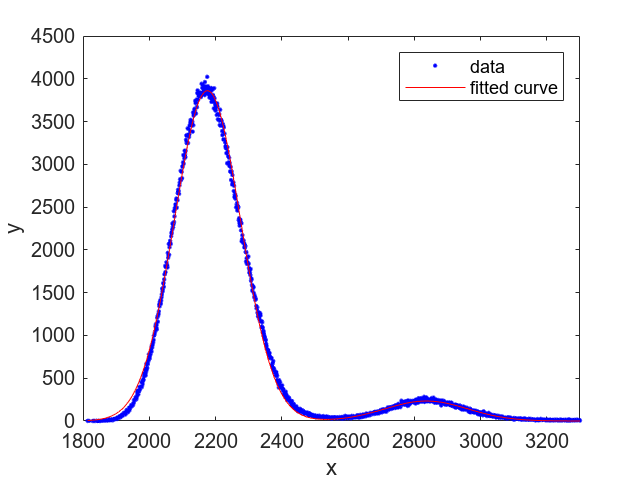


counts = dist.Values;
mask = counts~=0;
y = counts(mask);

bins = dist.BinEdges;
x = round(bins(mask));

gaus = fit(x.',y.','gauss2');
plot(gaus,x,y)
xlim([1800 3300])


mean_p15 = gaus.b1

mean_p15 = 2.1757e+03

sigma_p15 = gaus.c1/sqrt(2)

sigma_p15 = 100.1219


[e_mean, e_sigma] = fit_error(gaus)

e_mean = 0.1896

e_sigma = 0.1896

error_mean = [error_mean; e_mean];
error_sigma = [error_sigma; e_sigma];

mean = [mean_m30; mean_m25; mean_m20; mean_m15; mean_m10; mean_m05; mean_p00; mean_p05; mean_p10; mean_p15]*3.35;
error_mean = error_mean*3.35;

sigma = [sigma_m30; sigma_m25; sigma_m20; sigma_m15; sigma_m10; sigma_m05; sigma_p00; sigma_p05; sigma_p10; sigma_p15]*3.35

sigma =     6.8297
    7.1721
    7.8812
    9.4376
   12.9496
   20.4596
   37.1841
   74.3498
  158.6376
  335.4082


error_sigma = error_sigma*3.35

error_sigma =     0.0060
    0.0074
    0.0308
    0.0214
    0.0319
    0.0494
    0.0827
    0.1580
    0.3155
    0.6353


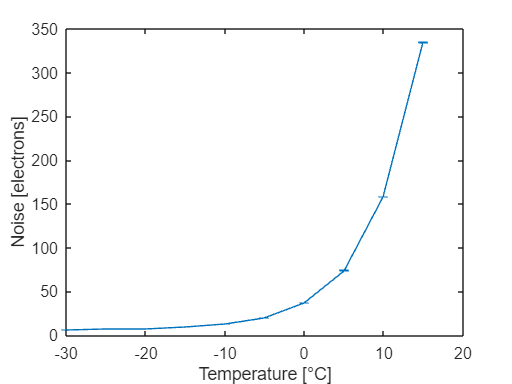


temperature = [-30; -25; -20; -15; -10; -5; 0; 5; 10;  15];

errorbar(temperature, sigma, error_sigma)
xlabel("Temperature [°C]")
ylabel("Noise [electrons]")